## 書店データ分析：Step 1 - データ理解と基礎分析

clear; clc; close all;

### 1.データのインポートは「rawData.mat」を実行

### 2. 基本統計の確認

% 期間の確認
dateRange = [min(rawData_dailySales.Date), max(rawData_dailySales.Date)];
fprintf('データ期間: %s 〜 %s\n', ...
    datestr(dateRange(1)), datestr(dateRange(2)));

データ期間: 01-Jan-2024 〜 31-Dec-2024


% 店舗数
nStores = length(unique(rawData_dailySales.BookstoreCode));
fprintf('店舗数: %d店舗\n', nStores);

店舗数: 35店舗


% カテゴリ数の確認
nMajorCat = length(unique(rawData_dailySales.MajorCategory));
fprintf('大分類カテゴリ数: %d\n', nMajorCat);

大分類カテゴリ数: 7051


% 総販売冊数
totalBooks = sum(rawData_dailySales.POSSalesVolume);
fprintf('総販売冊数: %d冊\n', totalBooks);

総販売冊数: 4706637冊


### 3. 売れ筋カテゴリの分析（top10）

% カテゴリ別集計
categoryStats = grpstats(rawData_dailySales, 'MajorCategory', ...
    {'sum', 'mean'}, 'DataVars', 'POSSalesVolume');
categoryStats = sortrows(categoryStats, 'sum_POSSalesVolume', 'descend');

% TOP10表示
top10 = categoryStats(1:min(10, height(categoryStats)), :);
fprintf('\n順位 | カテゴリ名 | 販売冊数 | 平均販売数\n');


順位 | カテゴリ名 | 販売冊数 | 平均販売数


fprintf('----------------------------------------\n');

----------------------------------------


for i = 1:height(top10)
    catName = char(top10.MajorCategory(i));
    % 文字化けを防ぐため、表示を調整
    if length(catName) > 20
        catName = [catName(1:17) '...'];
    end
    fprintf('%2d位 | %-20s | %6d冊 | %.1f冊\n', ...
        i, catName, top10.sum_POSSalesVolume(i), top10.mean_POSSalesVolume(i));
end

 1位 | コミック                 | 1383186冊 | 1.3冊
 2位 | 月刊誌                  | 856595冊 | 1.3冊
 3位 | 文庫                   | 630459冊 | 1.1冊
 4位 | 児童                   | 325607冊 | 1.1冊
 5位 | 週刊誌                  | 199600冊 | 2.0冊
 6位 | 趣味                   | 180914冊 | 1.1冊
 7位 | 生活                   | 137308冊 | 1.1冊
 8位 | 文芸                   | 111247冊 | 1.1冊
 9位 | 地図・ガイド               | 104020冊 | 1.0冊
10位 | ビジネス                 |  99534冊 | 1.1冊


### 4. カテゴリ販売の可視化

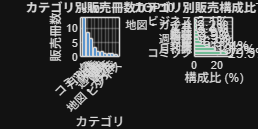

figure('Name', '売れ筋カテゴリ分析', 'Position', [100 100 1200 600]);

% サブプロット1: 販売冊数TOP10
subplot(1, 2, 1);
bar(1:height(top10), top10.sum_POSSalesVolume, 'FaceColor', [0.2 0.5 0.8]);
xlabel('カテゴリ');
ylabel('販売冊数');
title('カテゴリ別販売冊数TOP10');
xticks(1:height(top10));
xticklabels(top10.MajorCategory);
xtickangle(45);
grid on;

% サブプロット2: 構成比（水平棒グラフ）
subplot(1, 2, 2);
numTop = min(10, height(top10));
topSales = top10.sum_POSSalesVolume(1:numTop);
totalSales = sum(categoryStats.sum_POSSalesVolume);
topPercentages = (topSales / totalSales) * 100;

barh(1:numTop, topPercentages, 'FaceColor', [0.3 0.7 0.5]);
yticks(1:numTop);
yticklabels(top10.MajorCategory(1:numTop));
xlabel('構成比 (%)');
title('カテゴリ別販売構成比TOP10');
grid on;

% パーセンテージを棒の右側に表示
for i = 1:numTop
    text(topPercentages(i) + 0.5, i, sprintf('%.1f%%', topPercentages(i)), ...
        'VerticalAlignment', 'middle');
end
xlim([0 max(topPercentages) * 1.15]);

### 5. 日別・カテゴリ別の集計（次のステップの準備）

dailyCategory = grpstats(rawData_dailySales, {'Date', 'MajorCategory'}, ...
    'sum', 'DataVars', 'POSSalesVolume');

uniqueDates = unique(dailyCategory.Date);
uniqueCategories = unique(dailyCategory.MajorCategory);
nDates = length(uniqueDates);
nCategories = length(uniqueCategories);

% カテゴリ×日付のマトリクス作成
salesMatrix = zeros(nCategories, nDates);
for i = 1:height(dailyCategory)
    catIdx = find(uniqueCategories == dailyCategory.MajorCategory(i));
    dateIdx = find(uniqueDates == dailyCategory.Date(i));
    salesMatrix(catIdx, dateIdx) = dailyCategory.sum_POSSalesVolume(i);
end
fprintf('作成した行列サイズ: %d カテゴリ × %d 日\n', nCategories, nDates);

作成した行列サイズ: 34 カテゴリ × 366 日


### 6. 簡単な相関分析（次への橋渡し）

validCategories = std(salesMatrix, 0, 2) > 0;
validSalesMatrix = salesMatrix(validCategories, :);
validCategoryNames = uniqueCategories(validCategories);

corrMatrix = corrcoef(validSalesMatrix');
corrUpper = triu(corrMatrix, 1);
[sortedCorr, sortedIdx] = sort(corrUpper(:), 'descend');

validIdx = find(sortedCorr > 0 & sortedCorr < 1);
topIdx = validIdx(1:min(3, length(validIdx)));

fprintf('\n関連性の高いカテゴリペア:\n');


関連性の高いカテゴリペア:


for i = 1:length(topIdx)
    [row, col] = ind2sub(size(corrMatrix), sortedIdx(topIdx(i)));
    fprintf(' %s ←→ %s (相関: %.3f)\n', ...
        char(validCategoryNames(row)), ...
        char(validCategoryNames(col)), ...
        sortedCorr(topIdx(i)));
end

 日記手帳 ←→ 趣味 (相関: 0.934)
 生活 ←→ 趣味 (相関: 0.853)
 日記手帳 ←→ 生活 (相関: 0.810)


### 7. 結果の保存と次のステップ案内

% 【修正v2】TOP10カテゴリとその販売行列を正しく抽出

% TOP10カテゴリ名を取得
top10Categories = categoryStats.MajorCategory(1:10);

% ismember()を使用してインデックスを正しく取得
[isMember, top10IdxMapping] = ismember(top10Categories, uniqueCategories);

% 全TOP10カテゴリがuniqueCategories内に存在することを確認
if sum(isMember) ~= length(top10Categories)
    error('一部のTOP10カテゴリがuniqueCategories内に見つかりません');
end

% TOP10の販売行列を抽出（順序を保持）
top10SalesMatrix = salesMatrix(top10IdxMapping, :);

% 検証: 行列サイズの確認
fprintf('\n【TOP10データの検証】\n');


【TOP10データの検証】


fprintf('  TOP10カテゴリ数: %d\n', length(top10Categories));

  TOP10カテゴリ数: 10


fprintf('  TOP10販売行列サイズ: %d × %d\n', size(top10SalesMatrix, 1), size(top10SalesMatrix, 2));

  TOP10販売行列サイズ: 10 × 366


fprintf('  各カテゴリの総販売数:\n');

  各カテゴリの総販売数:


for i = 1:length(top10Categories)
    fprintf('    %d. %s: %d冊\n', i, char(top10Categories(i)), sum(top10SalesMatrix(i, :)));
end

    1. コミック: 1383186冊
    2. 月刊誌: 856595冊
    3. 文庫: 630459冊
    4. 児童: 325607冊
    5. 週刊誌: 199600冊
    6. 趣味: 180914冊
    7. 生活: 137308冊
    8. 文芸: 111247冊
    9. 地図・ガイド: 104020冊
    10. ビジネス: 99534冊



% 保存データの構築
analysisData.salesMatrix = salesMatrix;  % 全カテゴリ（後方互換性）
analysisData.uniqueCategories = uniqueCategories;  % 全カテゴリ（後方互換性）
analysisData.uniqueDates = uniqueDates;
analysisData.categoryStats = categoryStats;

% 【追加】TOP10専用データ
analysisData.top10Categories = top10Categories;
analysisData.top10SalesMatrix = top10SalesMatrix;

save('step1_results.mat', 'analysisData');
fprintf('\n結果を step1_results.mat に保存しました\n');


結果を step1_results.mat に保存しました


fprintf('  - 全カテゴリ数: %d\n', nCategories);

  - 全カテゴリ数: 34


fprintf('  - TOP10カテゴリ数: %d\n', length(top10Categories));

  - TOP10カテゴリ数: 10
